# M1 AHU Vibration Analysis

This script uses the AHU vibration power spectrum density (PSD) $U_\text{seg}(j\omega)$ and the telescope frequency response $H(j\omega)$ to perform a set of analysis regarding the impact of the vibration load into the image quality.

Preamble

- Clear workspace

- Radians to mas ($10^{-3}$ arc seconds) conversion constant

clearvars
rad2mas = (180/pi * 3600 * 1000);   % Radians to mili arc second conversion constant
rss = @(x,dir)sqrt(sum(x.^2,dir));  % Root of the sum of squared values function

## Load AHU vibration PSD

load("ahu_psd_1KHz_1400rpm.mat","psdAHUf","freq");

`psdAHUf` provides the vibration power spectrum density (PSD) data $U_\text{seg}(j\omega)$ as an $n_f \times 6$ matrix, where $n_f$ is the number of frequency samples. The frequencies in (Hz) are available from `freq.` The columns are the forces ($F_x$, $F_y$, and $F_z$) and moments ($M_x$, $M_y$, and $M_z$), expressed in $\text{N}^2/\text{Hz}$ and $\text{N}^2\text{m}^2/\text{Hz}$, respectively.

## Get NS or LTAO RTF matrix

The variable `rtf` is a $21\times21$matrix transfer function. The NS or LTAO (depending on the argument state of `NS_MODE`) tip-tilt rejection transfer function (RTF) fills the first 14 main diagonal entries. The differential piston RTF fills the last 7 diagonal elements if the checkbox is unchecked, meaning that one assumes the LTAO observing mode. Otherwise, those diagonals are filled with 1s. The rejection transfer function matrix aims at reproducing the effect of the wavefront control loops.

om = 2*pi*freq;
NS_MODE =  false;   % Check to choose Natural Seeing RTFs
if(NS_MODE)
    rtf(1:14,1:14) = eye(14)*frd(oad_NS_rtf(om),om); %#ok<*UNRCH> 
    rtf(15:21,15:21) = eye(7)*frd(tf(1,1),om);
else    
    rtf(1:14,1:14) = eye(14)*frd(oad_AOTT_rtf(om),om);
    rtf(15:21,15:21) = eye(7)*frd(getRTF_DP(om),om);
end

## General analysis

Let $G(\j\omega)$the frequency response matrix represent the GMT structural dynamics whose inputs are the forces and moments applied to nodes at the M1 fan locations and the outputs are the M1 and M2 rigid-body motions. As illustrated in the model diagram below, using a linear approximation (LOM), one gets the segment tip-tilt (TT) and the piston at the exit pupil.

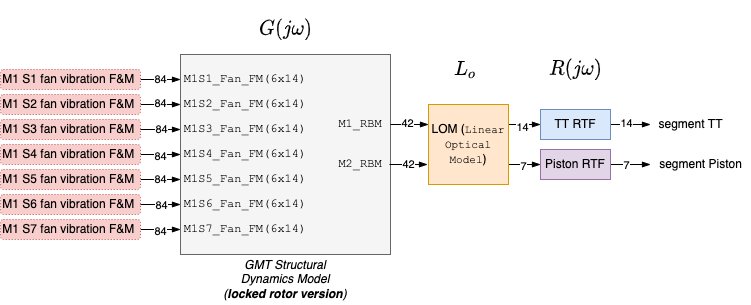

Therefore, the full telescope model reads as

$H(j\omega) = R(j\omega) L_o G(j\omega)$, 

where $R(j\omega)$ and $L_o$ represent the rejection transfer function frequency response matrix and the linear optical model transformation, respectively.

In the following, we compute the TT and piston PSD ($$\text{mas}^2/\text{Hz}$$ and $$\text{nm}^2/\text{Hz}$$, respectively) using 


$$Y_\text{TTP}(j\omega) = \left|H(j\omega) \right|^2
\left(\mathbf{1}_{84} \otimes U_{\text{seg}}(j\omega)\right)$$


The symbol $
\otimes$stands for the Kronecker product and $\mathbf{1}_{n_1}$ is an $n_1$-dimensional column vector filled with ones, such that

$\mathbf{1}_3 \otimes U_\text{seg}(j\omega) = \left[
\begin{array}{c}
U_\text{seg}(j\omega) \\ U_\text{seg}(j\omega) \\ U_\text{seg}(j\omega)
\end{array}
\right]$.

Therefore, $\mathbf{1}_{84} \otimes U_\text{seg}(j\omega)$ means that the same force and moment vibration load $U_\text{seg}$ is applied in all the fan nodes. The power spectrum density $Y_\text{TTP}$ is 21-dimensional. According to the telescope frequency response model, the first 14 elements of $Y_\text{TTP}$ are the tip-tilt PSD and the last 7 provide the segment piston.

In terms of implementation, the telescope frequency response representing the effect of the load applied on each M1 segment is available from a different data file (`m1s``X``fanTF.mat`) computed beforehand. For this reason, the code below performs two `for` loops: an outer one, which considers the frequency response model due to the excitation on each segment, and an inner iteration, to compute the tip-tilt and piston PSD of each segment. 

for k1 = 1:7
    % Load segment <k1> TF
    load(sprintf("m1s%dfanTF.mat",k1),"G_fr","ik");
    if(0), fprintf("Segment %d TF file loaded successfully! ",k1); end 
    n_om = length(G_fr.Frequency);
    % Check if PSD and TF frequencies match
    if(~isequal(G_fr.Frequency,om(1:n_om)))
        error("PSD and TF frequencies do not match!")
    end
    % Apply NS/LTAO RTF
    rtf = frd(rtf.ResponseData(1,1,1:n_om), rtf.Frequency(1:n_om));
    Gtel_rtf_fr = rtf * G_fr;
    
    % Initialize variables 
    if(~exist("tt_psd","var")), tt_psd = zeros(14,7,n_om); end
    if(~exist("piston_psd","var")), piston_psd = zeros(7,7,n_om); end
    
    Useg = kron(ones(1,14),psdAHUf(1:n_om,:));
    % PTT computation loop: each iteration provides the Tip/tilt/piston PSD
    % of segment S<k2> as a response of the AHU vibration forces applied on S<k1>. 
    for k2 = 1:7
        tt_psd(k2,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2,:,:)))'.^2 .* Useg,2);
        tt_psd(k2+7,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2+7,:,:)))'.^2 .* Useg,2);
        piston_psd(k2,k1,:) = sum(abs(squeeze(Gtel_rtf_fr.ResponseData(k2+14,:,:)))'.^2 .* Useg,2);
    end
    fprintf("TT and Piston PSD computed for S%d.\n",k1);
end

TT and Piston PSD computed for S1.
TT and Piston PSD computed for S2.
TT and Piston PSD computed for S3.
TT and Piston PSD computed for S4.
TT and Piston PSD computed for S5.
TT and Piston PSD computed for S6.
TT and Piston PSD computed for S7.


### Cumulative TT and Piston Power Spectrum Densities

Below, we present the cumulative power spectrum (CPS). Each line represents the effect of the load applied on a particular M1 segment.

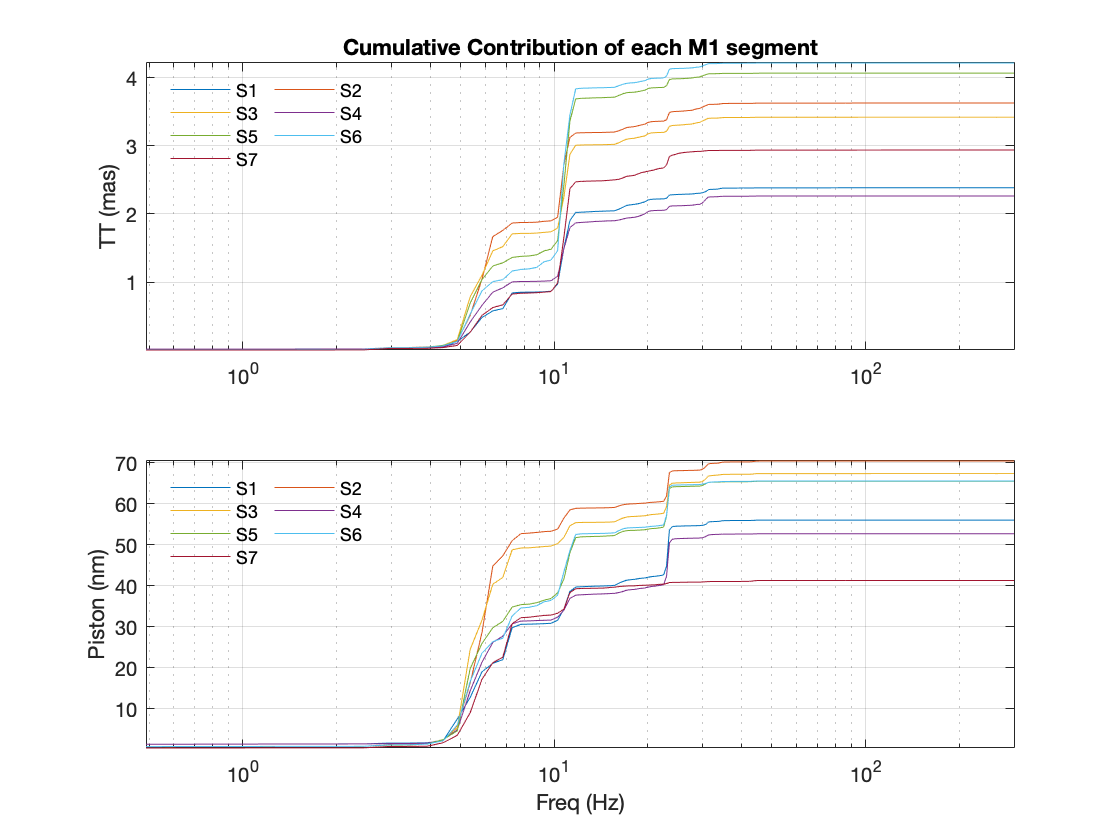

DeltaFs = diff(om(1:2)/2/pi);
w = om(2:n_om);

figure(200);
for i1 = 1:7    
    subplot(211);
    tt_cumPSD_mas = rad2mas*sqrt( DeltaFs*( cumsum(sum(tt_psd(1:7,i1,2:end),1).^2) +...
        cumsum(sqrt(sum(tt_psd(7:14,i1,2:end),1).^2)) ));
    
    semilogx(w/2/pi, squeeze(tt_cumPSD_mas)); hold on;
    subplot(212);
    semilogx(w/2/pi, squeeze(1e9*sqrt(DeltaFs*cumsum( sum(piston_psd(:,i1,2:end),1) )))); hold on;
end

subplot(211);
title('Cumulative Contribution of each M1 segment');
ylabel('TT (mas)');
grid on; hold off; axis tight;
legend('S1','S2','S3','S4','S5','S6','S7','Orientation','Horizontal',...
    'Location','northwest','NumColumns',2); legend boxoff;

subplot(212)
ylabel('Piston (nm)');
xlabel('Freq (Hz)');
grid on; hold off; axis tight;
legend('S1','S2','S3','S4','S5','S6','S7','Orientation','Horizontal',...
    'Location','northwest','NumColumns',2); legend boxoff;

### Overall PTT effect and WFE

Let the $Y_i(j \omega)$ the $i^\text{th}$ element of $Y_\text{TTP}(j\omega)$, we compute the overall TT (in mas) as


$$\phi = 
\sqrt{\frac{1}{7}\int_0^{\infty} \sum_{i=1}^{14} Y_i(j\omega) d\omega }.$$


Similarly, the overall differential piston (in meters) reads as


$$\rho = \sqrt{\frac{1}{7}\int_0^{\infty} \sum_{i=15}^{21} Y_i(j\omega) d\omega }.$$


As proposed in GMT-DOC-04861, the $1/7$ factor aims at taking the mean tip-tilt and differential piston over the contributions of all segments. Thus, the expression of the overall M1 AHU vibration effect on the wavefront error (WFE) in (in meters) is

$\text{WFE} = \sqrt{\frac{R^2}{4} \left(3.6\times 10^6\frac{\pi}{180}\phi\right)^2 + \rho^2}$,

where $R=8.4$m.

total_tt = rad2mas*sqrt( DeltaFs*sum(tt_psd(:,:,2:end), 'all') /7);
total_piston = 1e9*sqrt( DeltaFs*sum(piston_psd(:,:,2:end),'all') /7);

R = 8.4;    
total_wfe = sqrt(((total_tt/rad2mas)^2 * R^2/4)*1e18 + total_piston^2);
fprintf("Overall optical metrics:\nTT=%.3gmas \t Piston=%.3gnm \t WFE=%.3gnm \n",...
    total_tt, total_piston, total_wfe);

Overall optical metrics:
TT=4.2mas 	 Piston=60.6nm 	 wfe=105nm 


## Rejection transfer functions (RTFs)

Function to compute the NS RTF (according to REQ-L3-OAD-35337)

function [rtf,L] = oad_NS_rtf(w) %#ok<DEFNU> 

% PZT closed-loop bandwidth (Hz)
fz = 25;
% PZT control loop damping
delta = 0.6;
% TT loop sampling period
T = 5e-3;
% TT sensor delay
tau = 6e-3;
% TT "integral gain" - actually the considered integral gain is gi/T
gi = 0.3;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the GLAO RTF (according to REQ-L3-OAD-35398)

function [rtf,L] = oad_AOTT_rtf(w)

% LTAO RTF (according to REQ-L3-OAD-35398)
fz = 800;       % ASM closed-loop bandwidth (Hz)
delta = 0.75;   % ASM control loop damping
T = 2e-3;   % TT loop sampling period
tau = 1e-3; % TT sensor delay
gi = 0.4;   % TT "integral gain"

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the differential piston RTF

function RTF_DP = getRTF_DP(om)
    
s = sqrt(-1)*om;

%% FROM DRD rev F
omz = 800*2*pi;
dz = .75;
Tp = 30;
taup= 6/1000;
gpi = .5;
Te = 2/1000;
taue = .1/1000;
geff = .8;

num = 1 + omz^2*geff*exp(-taue*s).*(exp(-Te*s)-1)./(Te*s.*    (omz^2+2*omz*dz*s+s.^2) );
den = 1 - omz^2*gpi*exp(-taup*s).*(exp(-Tp*s)-1)./(Tp^2*s.^2.*(omz^2+2*omz*dz*s+s.^2) );
RTF_DP = num./den;
    
end